**Exercise 1**

Let $X$ be a continuous random variable with cumulative distribution


$$F\left(x\right)=\left\lbrace \begin{array}{ll}
\;1-\frac{4}{x^2 }, & x>2\\
0, & x\le 2
\end{array}\right.$$


Calculate $P(X \leq 3)$, $P(X > 3)$ and $P(4 \leq X \leq 5)$.

clear; clc; close all;

syms F(x);
F(x) = piecewise(x <= 2, 0, x > 2, 1 - 4/x^2);

PXleq3 = F(3);
PXg3 = 1 - F(3);
P4leqXleq5 = F(5) - F(4);

fprintf("P(X <= 3) = %s ≈ %.3f\n", string(simplify(PXleq3)), double(PXleq3));

P(X <= 3) = 5/9 ≈ 0.556


fprintf("P(X >  3) = %s ≈ %.3f\n", string(simplify(PXg3)), double(PXg3));

P(X >  3) = 4/9 ≈ 0.444


fprintf("P(4 <= X <= 5) = %s ≈ %.3f\n", string(simplify(P4leqXleq5)), double(P4leqXleq5));

P(4 <= X <= 5) = 9/100 ≈ 0.090


**Exercise 2**

Consider a manufacturing process producing soap bars. The soap bars are within specifications if they have a weight of $80 \pm 0.1 g$. If the weight of the soap bars manufactured may be looked upon as a random variable having a normal distribution with $\mu = 80.05 g$ and $\sigma = 0.05 g$, what percentage of these bars will meet specifications on average? A relevant function in MATLAB is `normcdf()`.

mu = 80.05;
sigma = 0.05;

upper = 80 + 0.1

upper = 80.1000

lower = 80 - 0.1

lower = 79.9000


p = normcdf(upper, mu, sigma) - normcdf(lower, mu, sigma);
pct = p * 100;

fprintf("P(79.9 <= X <= 80.1) = %.6f => %.2f%%\n", p, pct);

P(79.9 <= X <= 80.1) = 0.839995 => 84.00%


**Exercise 3**

Consider a random variable $Z$ with standard normal distribution. Find the $\alpha$-score $z_{\alpha}$ such that $\alpha  =P(Z > z_{\alpha})$ for $\alpha = 0.25, 0.05, 0.01$. A relevant function in  MATLAB is `norminv()`.

alpha = [0.25 0.05 0.01];

z = norminv(1 - alpha);

fprintf("alpha      z_alpha\n");

alpha      z_alpha


fprintf("-------    -------\n");

-------    -------


for k = 1:numel(alpha)
  fprintf("%0.2f %12.4f\n", alpha(k), z(k));
end

0.25       0.6745
0.05       1.6449
0.01       2.3263


**Exercise 4**

Generate $n = 2,4,8,16,32,64,128,256,512,1024$ random numbers from a random variable $X$ having a normal distribution with mean 10 and variance 8. Use theese samples and plot the sample mean and sample variance as a function of $n$. Use a logarithmic scale on the $n$ axis. Also indicate the mean and variance of $X$ for comparison. Comment on your results. Relevant functions in MATLAB are `normrnd()`, `mean() and var()`.

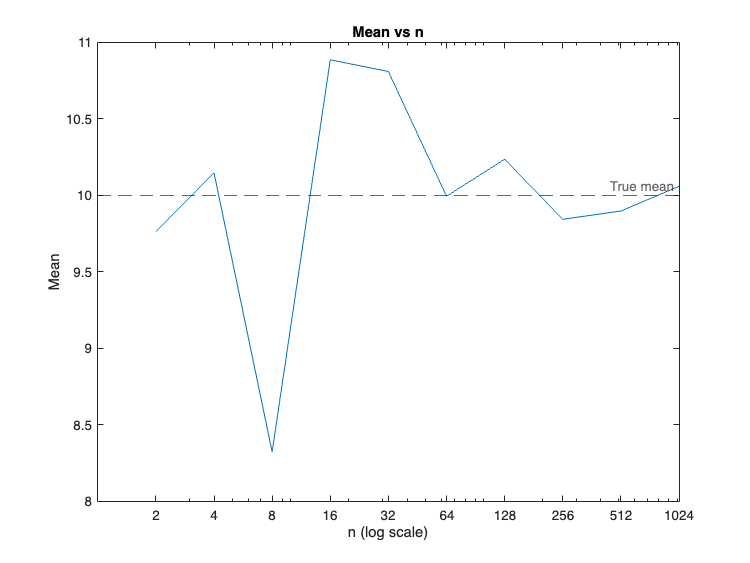

nvals = 2.^(1:10);

mu = 10;
varX = 8;
sigma = sqrt(varX);

means = zeros(size(nvals));
vars = zeros(size(nvals));

for i = 1:numel(nvals)
    n = nvals(i);
    x = normrnd(mu, sigma, [n, 1]);
    means(i) = mean(x);
    vars(i) = var(x);
end

figure;
semilogx(nvals, means);
set(gca, "XTick", nvals)
set(gca, "XTickLabel", string(nvals))
hold on;
yline(mu, "--", "True mean");
xlabel("n (log scale)");
ylabel("Mean");
title("Mean vs n")

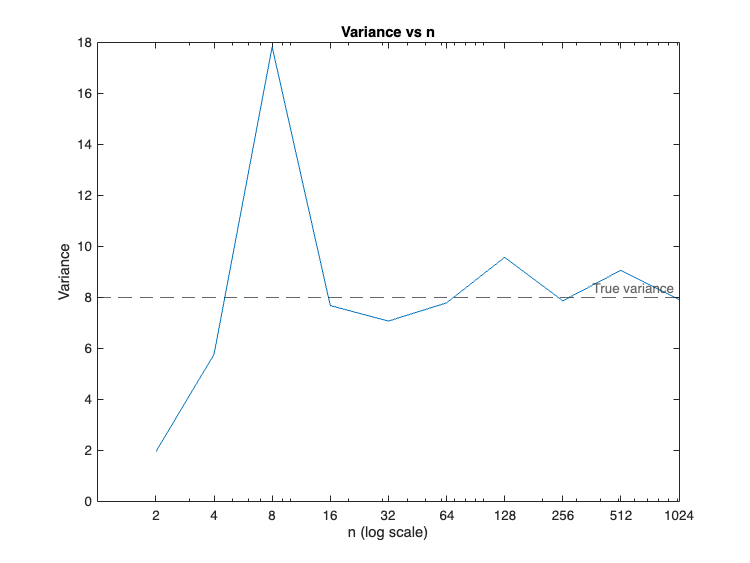


figure;
semilogx(nvals, vars);
set(gca, "XTick", nvals)
set(gca, "XTickLabel", string(nvals))
hold on;
yline(varX, "--", "True variance")
xlabel("n (log scale)");
ylabel("Variance");
title("Variance vs n")

hold off;

**Exercise 5**

Consider again a manufacturing process producing soap bars. The soap bars are within specifications if they have a weight of $80 \pm q g$. If the weight of the soap bars manufactured may be looked upon as a random variable having a normal distribution with $\mu = 80 g$ and $\sigma = 0.05 g$, find $q$ such that 90% of these bars will meet specifications on average?

*Hint*: The normal distribution is symmetric around its mean.

Note we want the central 90% of a normal distribution. This corresponds to leaving 5% at either end outside of spec by symmetry:

$P\left(80-q\le X\le 80+q\right)=0\ldotp 9$ => $P\left(X\le 80+q\right)=0\ldotp 95$

If we then standardize our variable then

$\frac{q}{\sigma \;}=z_{0\ldotp 95} =$`norminv(0.95) => `$q=\sigma \cdot \;$`norminv(0.95)`

mu = 80;
sigma = 0.05;

q = sigma * norminv(0.95);

fprintf("q = %.3f g\n", q);

q = 0.082 g


fprintf("Spec interval: [%.3f, %.3f] g\n", mu-q, mu+q);

Spec interval: [79.918, 80.082] g



% --- Result found through code:
qGrid = 0:1e-5:0.2;
p = normcdf(mu+qGrid,mu,sigma) - normcdf(mu-qGrid,mu,sigma);
pct = p * 100

pct =          0    0.0160    0.0319    0.0479    0.0638    0.0798    0.0957    0.1117    0.1277    0.1436    0.1596    0.1755    0.1915    0.2074    0.2234    0.2394    0.2553    0.2713    0.2872    0.3032    0.3192    0.3351    0.3511    0.3670    0.3830    0.3989    0.4149    0.4309    0.4468    0.4628    0.4787    0.4947    0.5106    0.5266    0.5426    0.5585    0.5745    0.5904    0.6064    0.6223    0.6383    0.6543    0.6702    0.6862    0.7021    0.7181    0.7340    0.7500    0.7660    0.7819



idx = find(p >= 0.90, 1, "first");
q_hat = qGrid(idx);

fprintf("q ≈ %.6f g (%.3f%% are within spec)\n", q_hat, pct(idx));

q ≈ 0.082250 g (90.003% are within spec)


**Exercise 6**

Let $X$ be a continuous random variable with probability density $f(x)$ and let


$$M\left(t\right)=E\left(e^{\mathrm{tX}} \right)$$


Assume that


$$M^{\left(k\right)} \left(0\right)={\left\lbrack \frac{d^k M\left(t\right)}{{\mathrm{dt}}^k }\right\rbrack }_{t=0}$$


exists and is finite for all $k$. Show that


$$M^{\left(k\right)} \left(0\right)={\mu_k }^{\prime }$$



$$M^{\left(k\right)} \left(0\right)={\left\lbrack \frac{d^k }{{\mathrm{dt}}^k }\int_{-\infty \;}^{\infty \;} e^{t\;x} \;f\left(x\right)\;\mathrm{dx}\right\rbrack }_{t=0} =\int_{-\infty \;}^{\infty \;} {\left\lbrack \frac{d^k e^{t\;x} }{{\mathrm{dt}}^k }\right\rbrack }_{t=0} f\left(x\right)\;\mathrm{dx}\;$$


Evaluating this gives


$$\int_{-\infty \;}^{\infty \;} {\left\lbrack \frac{d^k e^{t\;x} }{{\mathrm{dt}}^k }\right\rbrack }_{t=0} f\left(x\right)\;\mathrm{dx}\;=\int_{-\infty \;}^{\infty \;} x^k f\left(x\right)\;\mathrm{dx}=E\left(X^k \right)=\mu_k^{\prime }$$


**Exercise 7**

Let $X$ be a continuous random variable with mean $\mu$ and variance $\sigma^2$ and with probability density $f(x)$ and let $g$ and $h$ be functions and $a$ and $b$ be constants. Show that


$$E\left(a\;g\left(X\right)+b\;h\left(X\right)\right)=a\;E\left(g\left(x\right)\right)+b\;E\left(h\left(x\right)\right)$$


In particular, show that


$$\sigma {\;}^2 ={\mu_2 }^{\prime } -\mu^2$$



$$E\left(a\;g\left(X\right)+b\;h\left(X\right)\right)=\int_{-\infty \;}^{\infty \;} \left(a\;g\left(x\right)+b\;h\left(x\right)\right)f\left(x\right)\;\mathrm{dx}=a\;\int_{-\infty \;}^{\infty \;} g\left(x\right)\;f\left(x\right)\;\mathrm{dx}+b\int_{-\infty \;}^{\infty \;} h\left(x\right)\;f\left(x\right)\;\mathrm{dx}=a\;E\left(g\left(X\right)\right)+\mathrm{bE}\left(h\left(x\right)\right)$$



$$\sigma^2 =E\left({\left(X-\mu \;\right)}^2 \right)=E\left(X^2 -2X\mu +\mu^2 \right)=E\left(X^2 \right)+\mu^{2\;} -2\mu \;E\left(X\right)={\mu_2 }^{\prime } -\mu^2$$
